% AAE 532 HW 8 Problem 3
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps8';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
venus = planet_consts.venus;  % structure of venus
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
r_1 = earth.smao

r_1 = 149597898

r_2 = venus.smao

r_2 = 108207284


a_T = mean([r_1, r_2])

a_T = 128902591

e_T = (r_1 - r_2) / (r_2 + r_1)

e_T = 0.1605

p_T = a_T * (1 - e_T^2);
v_plus = vis_viva(r_1, a_T, sun.gp)

v_plus = 27.2892

v_minus = vis_viva(r_2, a_T, sun.gp)

v_minus = 37.7276

v_earth = sqrt(sun.gp / r_1)

v_earth = 29.7847

v_venus = sqrt(sun.gp / r_2)

v_venus = 35.0209

TOF = pi * sqrt(a_T^3 / sun.gp)

TOF = 1.2621e+07

TOF_years = TOF / 60 / 60 / 24 / 365

TOF_years = 0.4002

phi = rad2deg(pi - sqrt(sun.gp / r_2^3) * TOF)

phi = -54.0347

% (b)
v_inf_earth = abs(v_plus - v_earth)

v_inf_earth = 2.4955

v_c_earth = sqrt(earth.gp / (210 + earth.mer))

v_c_earth = 7.7784

Dv_dep = sqrt(v_inf_earth^2 + 2*earth.gp/(210 + earth.mer)) - v_c_earth

Dv_dep = 3.5014

% (c)
h_cap = 2000;
r_p_minus = r_2 - venus.mer - h_cap

r_p_minus = 1.0820e+08

r_a_minus = r_1 + earth.mer + 210

r_a_minus = 1.4960e+08

r_minus = r_p_minus

r_minus = 1.0820e+08

xi_minus = -sun.gp / 2 / a_T

xi_minus = -514.7780

v_inf_venus = v_minus - v_venus

v_inf_venus = 2.7067

v_c_venus = sqrt(venus.gp / (h_cap + venus.mer))

v_c_venus = 6.3518

Dv_arr = v_c_venus - sqrt(v_inf_venus^2 + 2*venus.gp / (h_cap + venus.mer)) 

Dv_arr = -3.0299

Dv_total = Dv_dep + Dv_arr

Dv_total = 0.4715

% (d)
r_plus = r_minus;
xi_fb = v_inf_venus^2 / 2

xi_fb = 3.6631

a_fb = -venus.gp / 2 / xi_fb

a_fb = -4.4342e+04

e_fb = 1 - (h_cap+venus.mer) / a_fb

e_fb = 1.1816

delta = 2*asind(1 / e_fb)

delta = 115.6271

v_plus = sqrt( v_inf_venus^2 + v_venus^2 - 2*v_inf_venus*v_venus*cosd(delta) )

v_plus = 36.2738

FPA_plus = asind(sind(delta) * v_inf_venus / v_plus)

FPA_plus = 3.8577


% True anomaly
temp = r_plus * v_plus^2 / sun.gp;
TA_plus = atand( temp*sind(FPA_plus)*cosd(FPA_plus) / ( temp*cosd(FPA_plus)^2 - 1 ))

TA_plus = 46.6849

Domega = 0 - TA_plus

Domega = -46.6849


% characterisitics
a_N = -sun.gp / 2 / (v_plus^2 / 2 - sun.gp / r_2)

a_N = 1.1671e+08

h_N = r_plus*v_plus*cosd(FPA_plus)

h_N = 3.9159e+09

p_N = h_N^2 / sun.gp

p_N = 1.1555e+08

e_N =  sqrt(1 - p_N / a_N)

e_N = 0.0998

r_aN = a_N * (1 + e_N)

r_aN = 1.2835e+08

r_pN = a_N * (1 - e_N)

r_pN = 1.0506e+08

xi_N = -sun.gp / 2 / a_N 

xi_N = -568.5710

IP_N = 2*pi * sqrt(a_N^3 / sun.gp)

IP_N = 2.1746e+07

IP_N_year = IP_N / 60 /60 / 24 / 365

IP_N_year = 0.6895

% (d)
Dv_eq = 2*v_inf_venus*sind((delta) / 2)

Dv_eq = 4.5815

alpha = 180 - (180 - delta) / 2

alpha = 147.8135

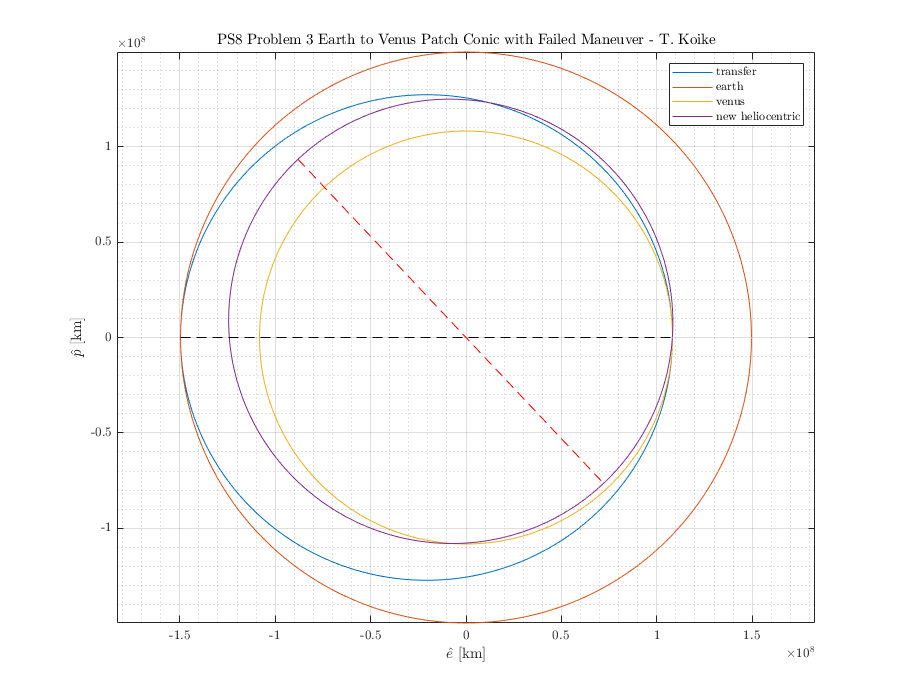

% (e)

% Plotting for visualization 
% transfer orbit
angles = 0:0.01:2*pi;
RR = p_T ./ (1 + e_T*cos(angles)); XX = RR.*cos(angles); YY = RR.*sin(angles);

% new orbit
RR_new = p_N ./ (1 + e_N*cos(angles - deg2rad(Domega)));
XX_new = RR_new.*cos(angles);
YY_new = RR_new.*sin(angles);
rp_vec = r_pN*[cosd(Domega), sind(Domega)];
ra_vec = r_aN*[cosd(Domega+180), sind(Domega+180)];

% Earth orbit
X_earth = earth.smao * cos(angles);
Y_earth = earth.smao * sin(angles);

% Venus orbit
X_venus = venus.smao * cos(angles);
Y_venus = venus.smao * sin(angles);

fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
    % old transfer orbit
    plot(XX,YY)
    hold on; grid on; grid minor; box on; axis equal; 
    
    % earth
    plot(X_earth, Y_earth, '-')
    
    % venus
    plot(X_venus, Y_venus, '-')
    
    % new heliocentric orbit
    plot(XX_new, YY_new, '-')
    
    plot([-r_1, r_2], [0, 0], '--k')
    plot([ra_vec(1), rp_vec(1)],[ra_vec(2), rp_vec(2)], '--r')
    hold off
    legend('transfer', 'earth', 'venus', 'new heliocentric')
    title('PS8 Problem 3 Earth to Venus Patch Conic with Failed Maneuver - T. Koike')
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, "p3-patch-conic.png"))